% syms s t;
s = tf('s');

student_num = [3 8 1 1 3 5 4 4];
sn_A = student_num(1) + 10;
sn_B = student_num(2) + 10;
sn_C = student_num(3) + 10;
sn_D = student_num(4) + 10;
sn_E = student_num(5) + 10;
sn_F = student_num(6) + 10;
sn_G = student_num(7) + 10;
sn_H = student_num(8) + 10;

J1 = (student_num(6)+10); % (Kgm^2)
J2 = J1;
J3 = (student_num(2)+10);
JM = J3;
K1 = (student_num(4)+10); % (Nm)
K3 = K1;
K2M = (student_num(5)+10);
K23 = K2M;
B1 = (student_num(7)+10); % (Nms)
B2 = (student_num(3)+10);
BM = (student_num(8)+10);
tauM = 3; % (Nm)

% convert these to the fucking electric ones kms

C1 = J1;
C2 = J2;
C3 = J3;
CM = JM;
L1 = 1/K1;
L3 = 1/K3;
L2M = 1/K2M;
L23 = 1/K23;
R1 = 1/B1;
R2 = 1/B2;
RM = 1/BM;
IM = tauM;

mat11 = CM*s + 1/RM + 1/R2 + 1/(L2M*s);
mat22 = 1/(L2M*s) + 1/R2 + 1/(L23*s) + 1/(L1*s) + C2*s;
mat33 = 1/(L1*s) + 1/R1 + C1*s;
mat44 = 1/(L23*s) + 1/R1 + 1/(L3*s) + C3*s;

mat12 = -1/(L2M*s) - 1/R2;
mat13 = 0;
mat14 = 0;

mat23 = -1/(L1*s);
mat24 = -1/(L23*s);

mat34 = -1/R1;

Y = [mat11, mat12, mat13, mat14; 
     mat12, mat22, mat23, mat24;
     mat13, mat23, mat33, mat34;
     mat14, mat24, mat34, mat44]

Y =
 
  From input 1 to output...
       1.385 s^2 + 1.923 s + 1
   1:  -----------------------
              0.07692 s
 
       -0.8462 s - 1
   2:  -------------
         0.07692 s
 
   3:  0
 
   4:  0
 
  From input 2 to output...
       -0.8462 s - 1
   1:  -------------
         0.07692 s
 
       0.008069 s^4 + 0.005917 s^3 + 0.0199 s^2
   2:  ----------------------------------------
                    0.0005379 s^3
 
          -1
   3:  ---------
       0.09091 s
 
          -1
   4:  ---------
       0.07692 s
 
  From input 3 to output...
   1:  0
 
          -1
   2:  ---------
       0.09091 s
 
       1.364 s^2 + 1.273 s + 1
   3:  -----------------------
              0.09091 s
 
   4:  -14
 
  From input 4 to output...
   1:  0
 
          -1
   2:  ---------
       0.07692 s
 
   3:  -14
 
       0.1259 s^3 + 0.0979 s^2 + 0.1678 s
   4:  ----------------------------------
                  0.006993 s^2
 
Continuous-time transfer function.




Z = inv(Y);

I = [IM; 0; 0; 0];

V = Z*I;
Vm = V(1);
V1 = V(3);
V2 = V(2);
V3 = V(4);

G1 = minreal(-(V2-Vm)/(L2M*s)/IM);
G2 = minreal((V3-V1)/(R1)/IM);

% calc1
[numG1, denG1] = tfdata(G1,'v');
[numG2, denG2] = tfdata(G2,'v');

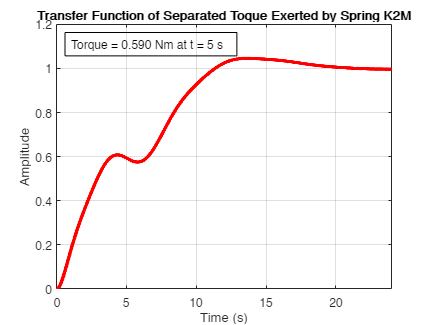

% fig 2
% torque == current? 

[y_1, t_1] = step(G1);
plot(t_1, y_1, 'LineWidth', 3, 'Color','Red')

grid on
title("Transfer Function of Separated Toque Exerted by Spring K2M")
xlabel("Time (s)")
ylabel("Amplitude")
axis([0, 24, 0, 1.2])
dim = [.15 .8 .3 .1];
annotation("textbox", dim, 'String', "Torque = 0.590 Nm at t = 5 s", "FitBoxToText","on")

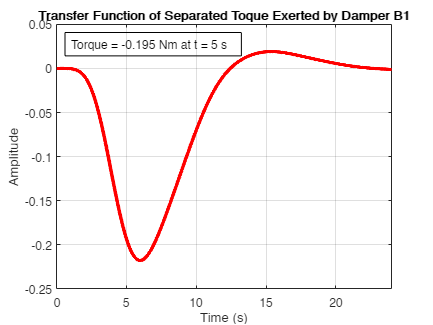


[y_2, t_2] = step(G2);
plot(t_2, y_2, 'LineWidth', 3, 'Color','Red')

grid on
title("Transfer Function of Separated Toque Exerted by Damper B1")
xlabel("Time (s)")
ylabel("Amplitude")
axis([0, 24, -0.25, 0.05])
dim = [.15 .8 .3 .1];
annotation("textbox", dim, 'String', "Torque = -0.195 Nm at t = 5 s", "FitBoxToText","on")

tau5fig = -0.195;
tau5calc = -0.1933;
err = (tau5fig - tau5calc)/tau5calc*100; % %

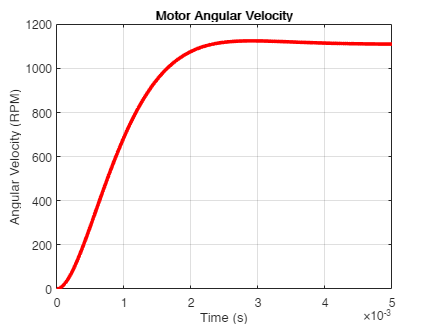

%  electro-mechnical stuff
s = tf('s');


Lw = (10 + sn_A)*1e-6;
Rw = (50 + sn_B)*1e-3;
B = sn_C*1e-6;
J = (sn_D + sn_E)*1e-6;
Kb = (sn_F + sn_G + sn_H)*1e-3;
Ktau = (sn_F + sn_G + sn_H)*1e-3;


motor_xfer = Ktau/((s^2*Lw*J)+s*(Lw*B+J*Rw)+Rw*B+Kb*Ktau);

% in rad so no need to multiply
[num, den] = tfdata(motor_xfer, 'v');

opt = stepDataOptions('StepAmplitude',5);
[y3, t3] = step(motor_xfer, opt);

plot(t3, y3*60/(2*pi), 'LineWidth', 3, 'Color','Red')
k = dcgain(tf(num,den));

grid on
title("Motor Angular Velocity")
xlabel("Time (s)")
ylabel("Angular Velocity (RPM)")
axis([0, 5e-3, 0, 1200])